# **Generalized chi-square distribution** · Getting started

The generalized chi-square variable is a quadratic form of a normal variable, or equivalently, a linear sum of independent non-central chi-square variables and a normal variable.

For more features and documentation, type:

doc gx2stat
doc gx2rnd
doc gx2cdf
doc gx2cdf_davies
doc gx2cdf_imhof
doc gx2cdf_ruben
doc gx2pdf
doc gx2inv
doc gx2_params_norm_quad 

If you use this toolbox, please cite: [A method to integrate and classify normal distributions](https://arxiv.org/abs/2012.14331).

Bugs/questions/comments to abhranil.das@utexas.edu.

Abhranil Das, Center for Perceptual Systems, University of Texas at Austin

## Calculate mean and variance

% gx2 parameters
w=[1 -10 2];
k=[1 2 3];
lambda=[2 3 7];
m=10;
s=5;

[mu,v]=gx2stat(w,k,lambda,m,s)

mu = -17

v = 1771

## Generate random samples

r=gx2rnd(w,k,lambda,m,s,[1 1e5]);

## Calculate pdf and cdf

x=[10 25];
f=gx2pdf(x,w,k,lambda,m,s)

f =     0.0121    0.0089


p=gx2cdf(x,w,k,lambda,m,s,'AbsTol',0,'RelTol',1e-4)

p =     0.7150    0.8790


### Compare calculated and sampled pdf's

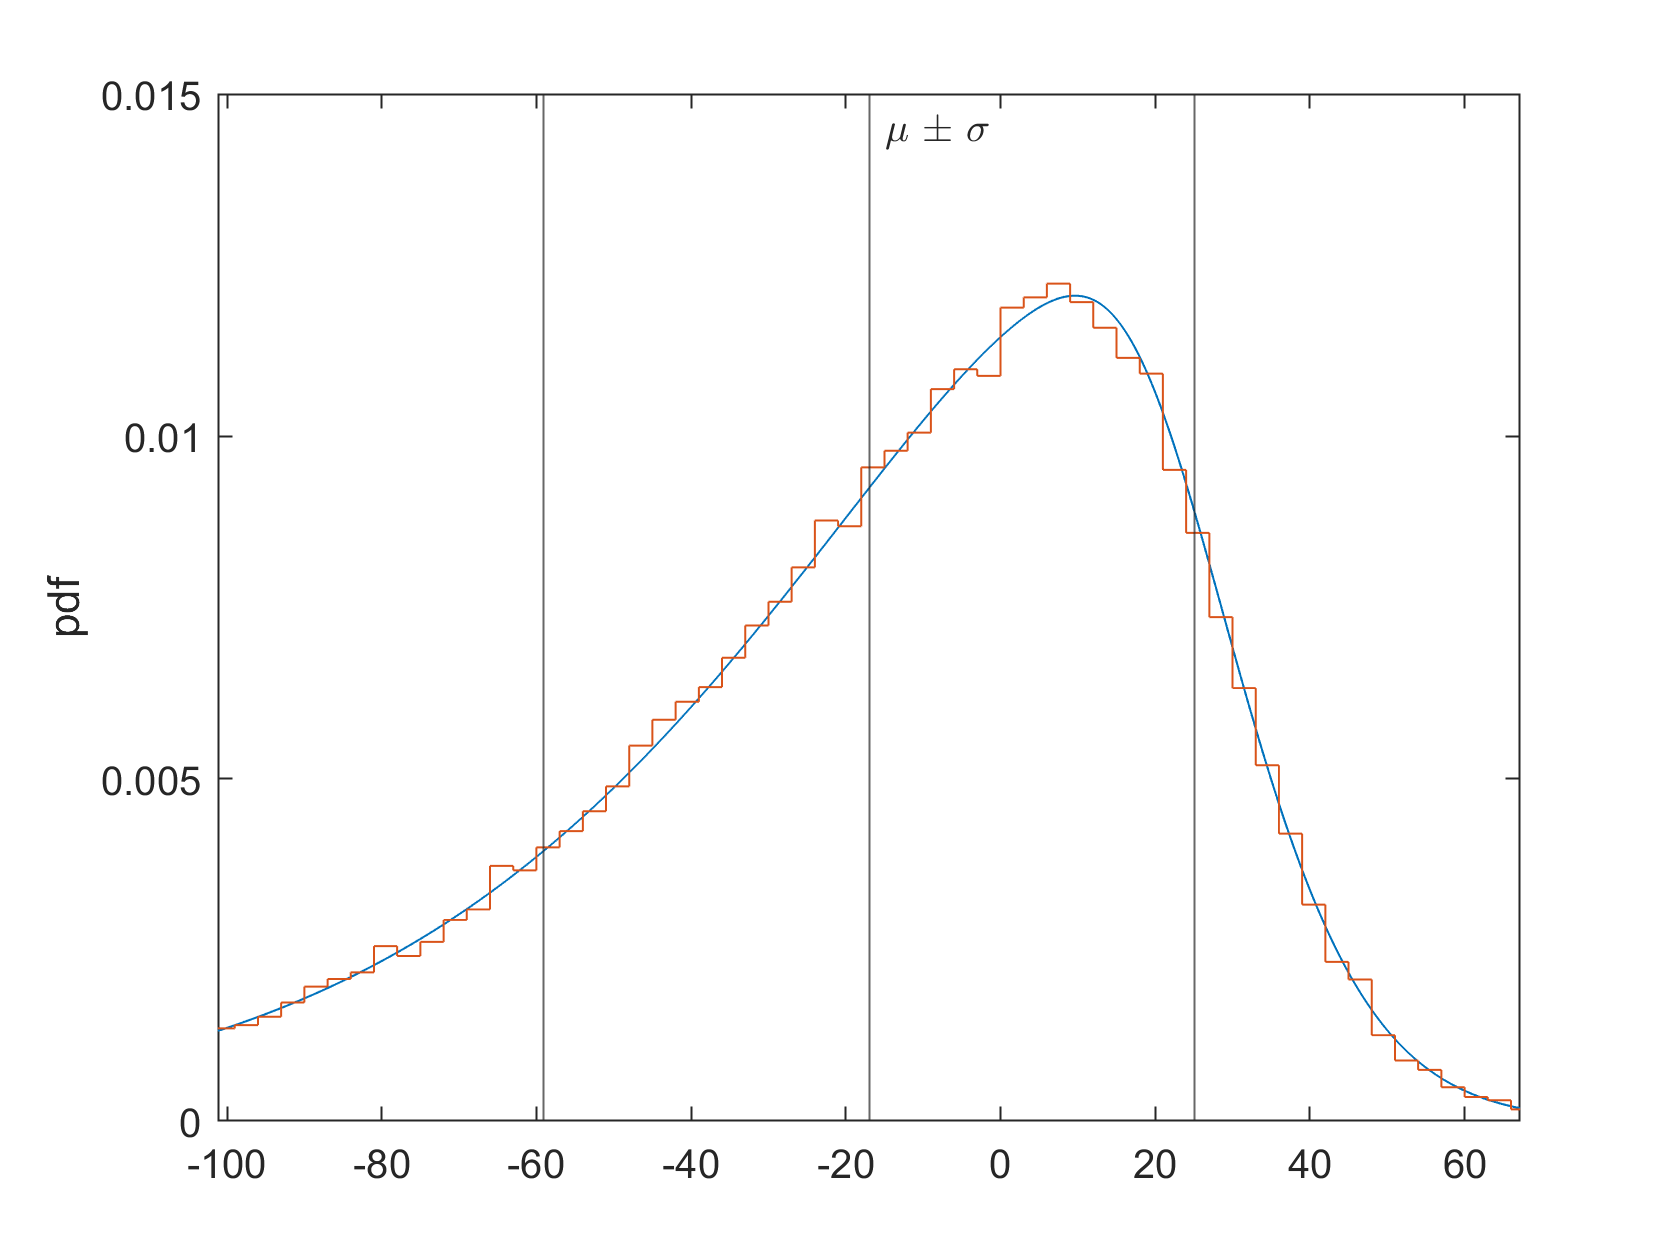

[f,x]=gx2pdf('full',w,k,lambda,m,s);
plot(x,f); hold on
histogram(r,'normalization','pdf','displaystyle','stairs')
xline(mu,'-',{'\mu \pm \sigma'},'labelorientation','horizontal');
xline(mu-sqrt(v),'-'); xline(mu+sqrt(v),'-');
xlim([mu-2*sqrt(v),mu+2*sqrt(v)]); ylim([0 .015]); ylabel 'pdf'

### Compare calculated and sampled cdf's

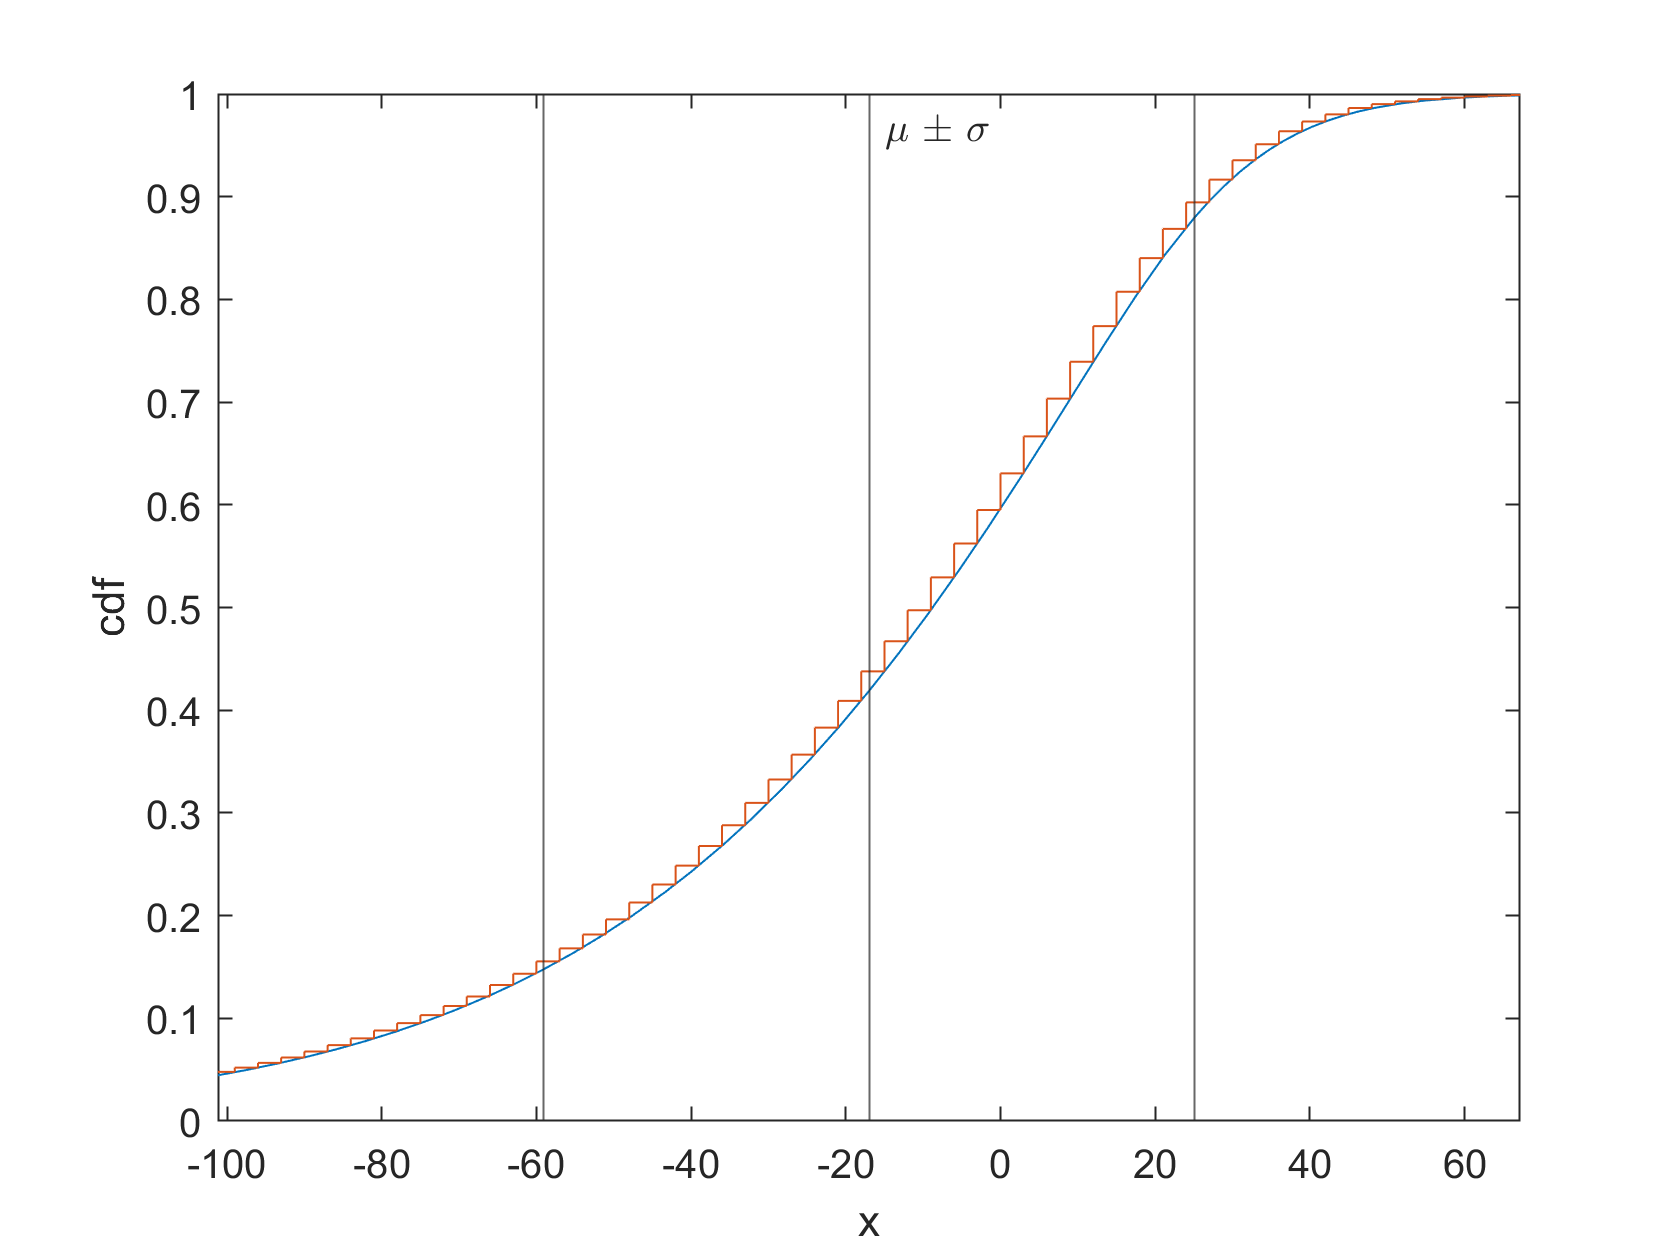

figure; fplot(@(x) gx2cdf(x,w,k,lambda,m,s));
hold on; histogram(r,'normalization','cdf','displaystyle','stairs')
xline(mu,'-',{'\mu \pm \sigma'},'labelorientation','horizontal');
xline(mu-sqrt(v),'-'); xline(mu+sqrt(v),'-');
xlim([mu-2*sqrt(v),mu+2*sqrt(v)]); ylim([0 1]); xlabel x; ylabel 'cdf'

## Compute inverse cdf

x=gx2inv([0.5 0.9],w,k,lambda,m,s)

x =    -8.7657   27.5320


## Distribution of quadratic form of a normal variable

Normal parameters:

mu=[5;6]; % mean
v=[2 1; 1 3]; % covariance matrix

Sample normal random vectors:

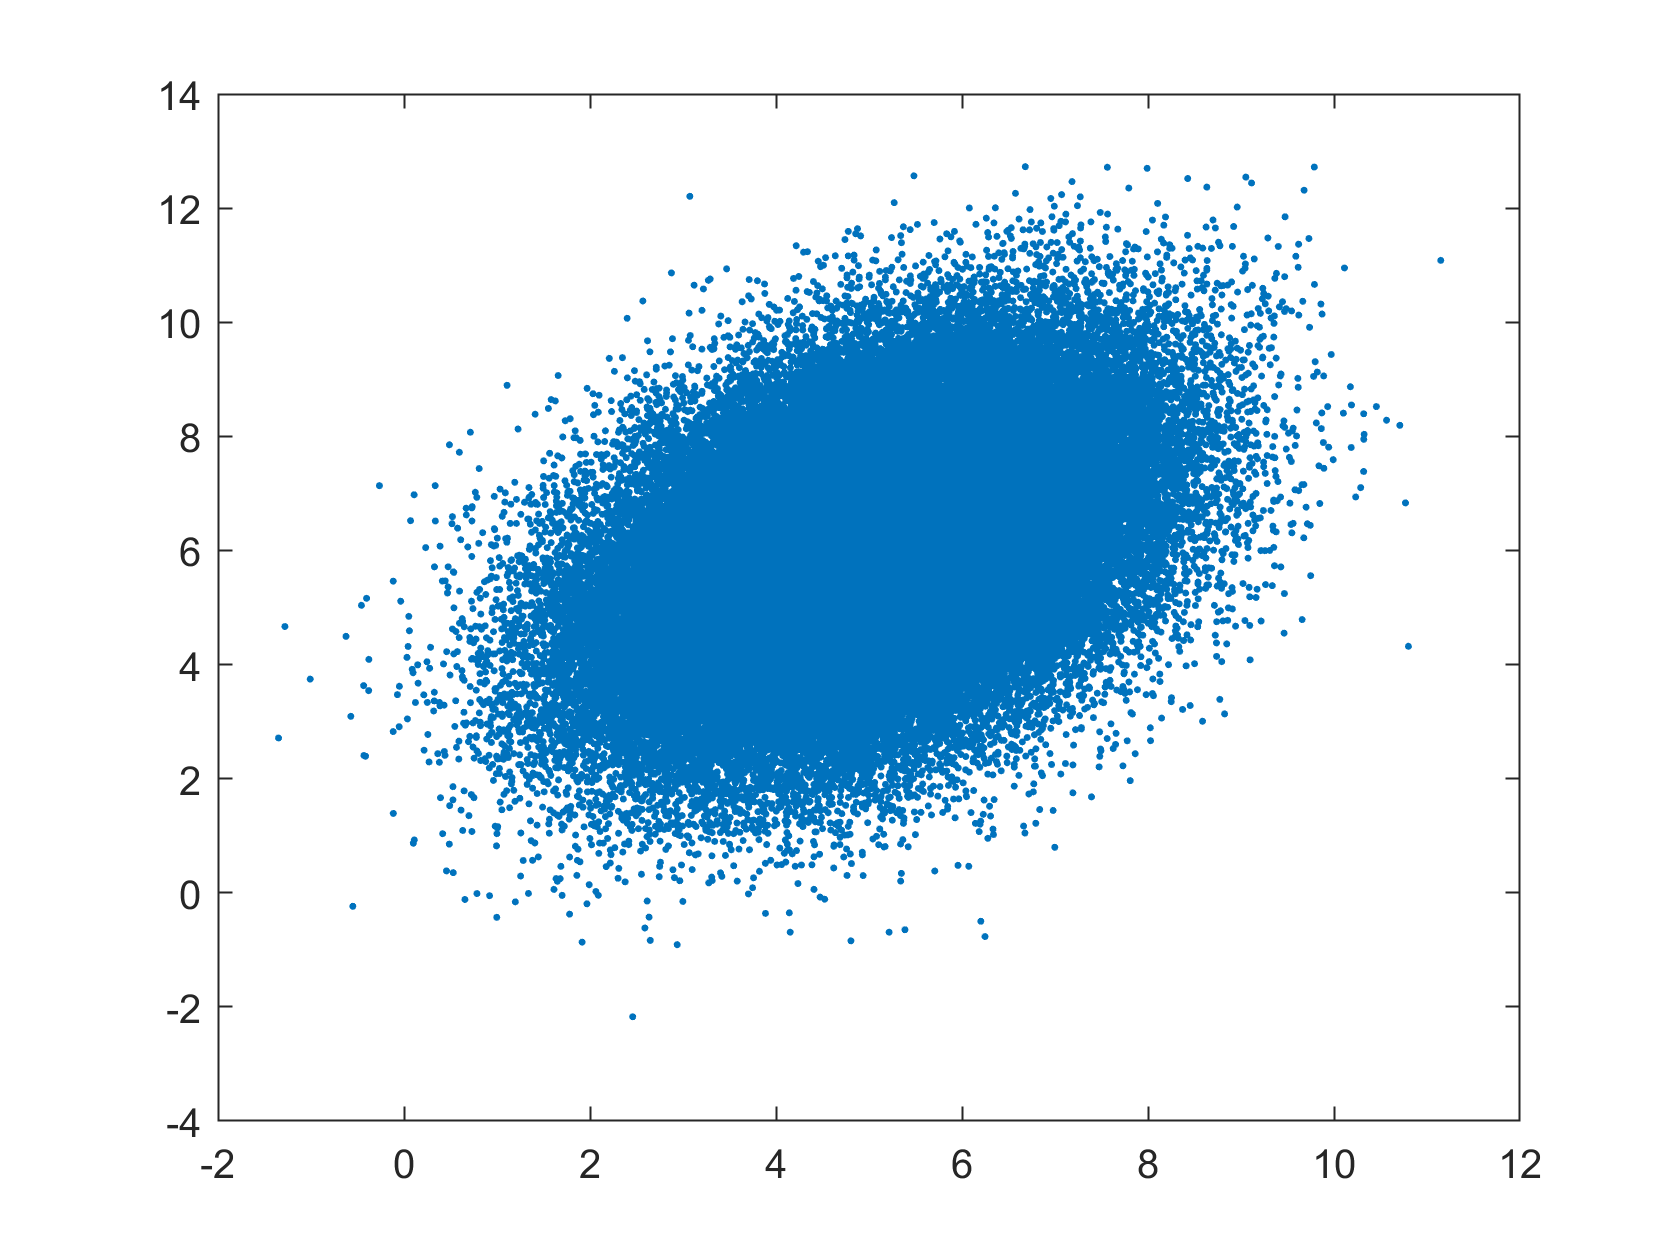

x=mvnrnd(mu,v,1e5)';
figure; plot(x(1,:),x(2,:),'.')

Quadratic form $q(\mathbf{x})=(x_1+x_2)^2-x_1-1$` = [x1;x2]'*[1 1; 1 1]*[x1;x2] + [-1;0]'*[x1;x2] -1`

quad.q2=[1 1; 1 1];
quad.q1=[-1;0];
quad.q0=-1;

Compute the quadratic form *q* for the sample of normal vectors:

q=dot(x,quad.q2*x)+quad.q1'*x+quad.q0;

Get generalized chi-square parameters corresponding to this quadratic form:

[w,k,lambda,m,s]=gx2_params_norm_quad(mu,v,quad)

w = 7.0000

k = 1

lambda = 16.6188

m = -1.3316

s = 0.8452

Compare the sampled and calculated distributions of *q*:

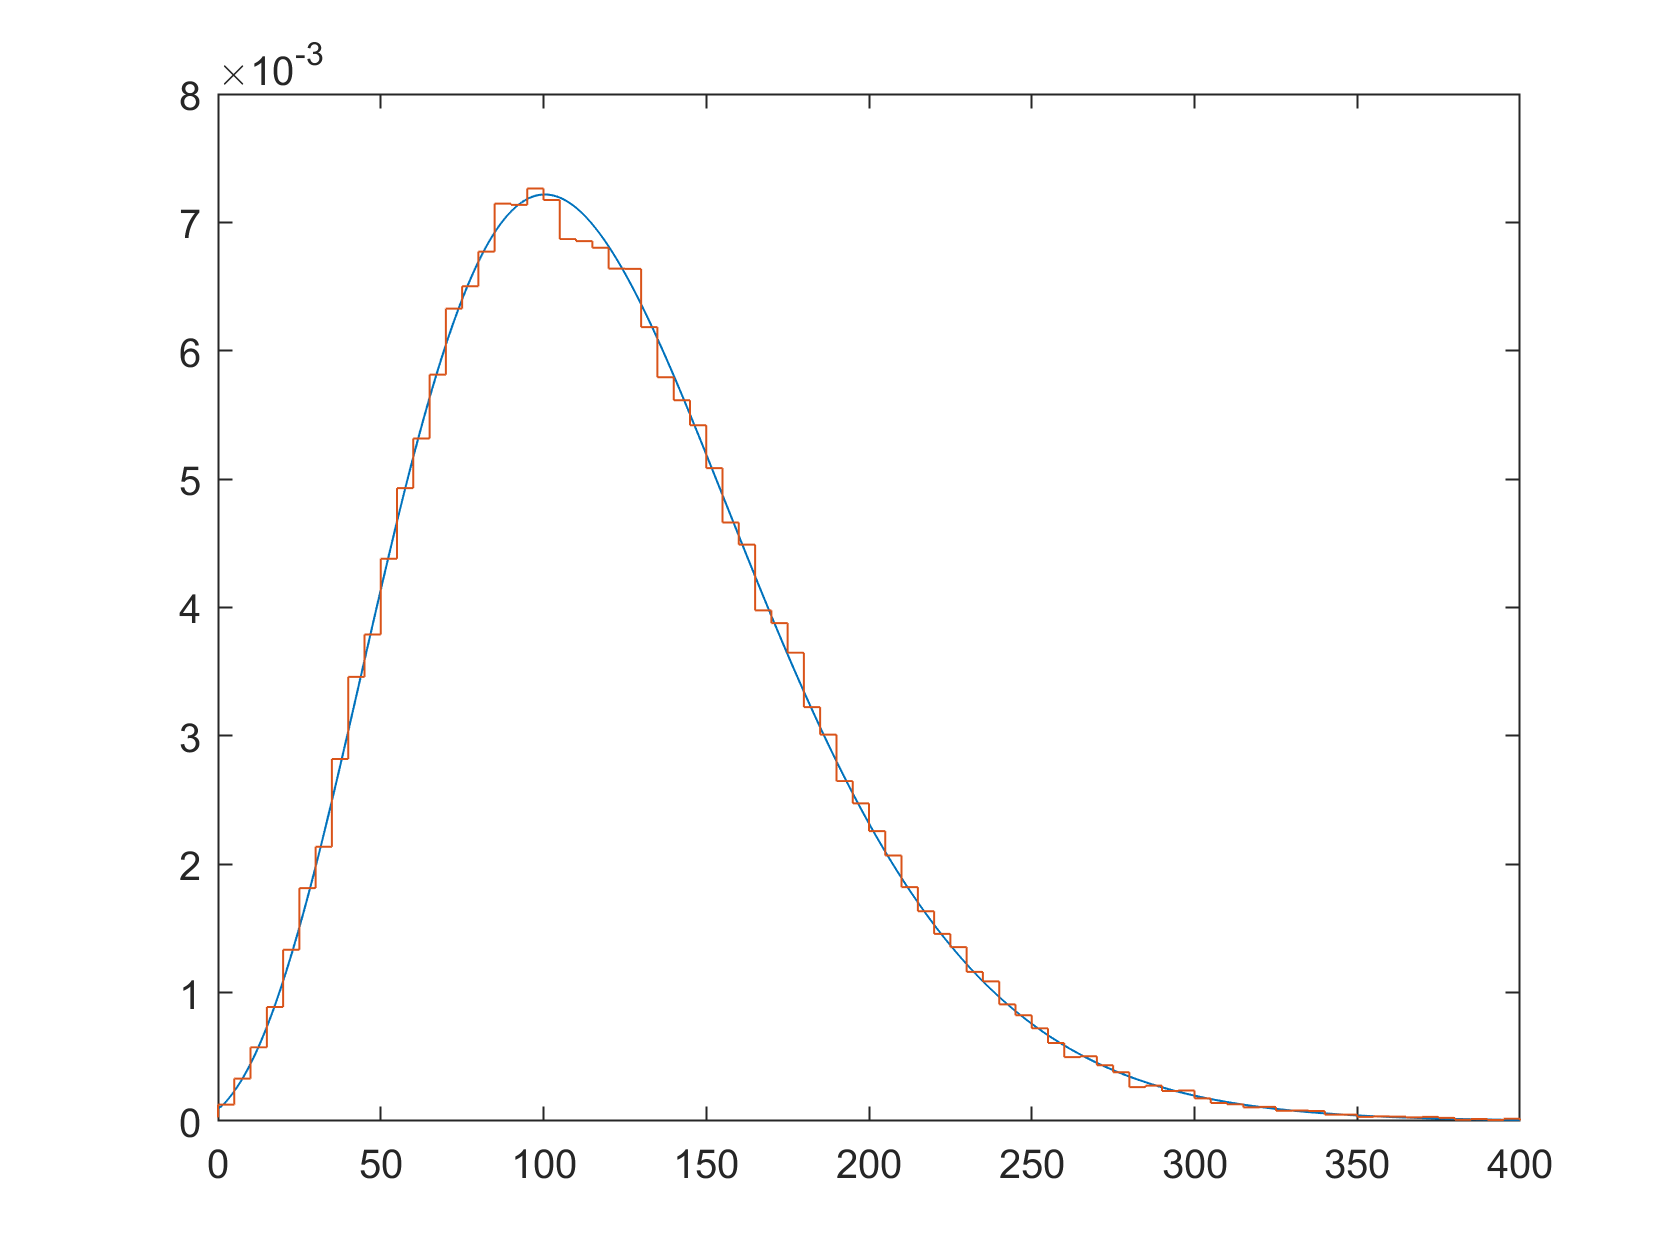

[f,x]=gx2pdf('full',w,k,lambda,m,s);
plot(x,f); hold on
histogram(q,'normalization','pdf','displaystyle','stairs')
xlim([0 400])

Compare the sampled and calculated means and variances:

[mu_q,v_q]=gx2stat(w,k,lambda,m,s);
[mu_q mean(q)]

ans =   122.0000  122.0815


[v_q var(q)]

ans = 	1.0e+03 *

    3.3560    3.3744


Compare the sampled and calculated probabilities $p(q(\mathbf{x})<50)$:

mean(q<50)

ans = 0.0865

gx2cdf(50,w,k,lambda,m,s)

ans = 0.0856